This live script solves the 2D first-order acoustic equations on staggered grids. Pressure satisfies homogeneous Dirichlet boundary conditions. Because this baseline solver has no PML, waves reflect from the boundary.

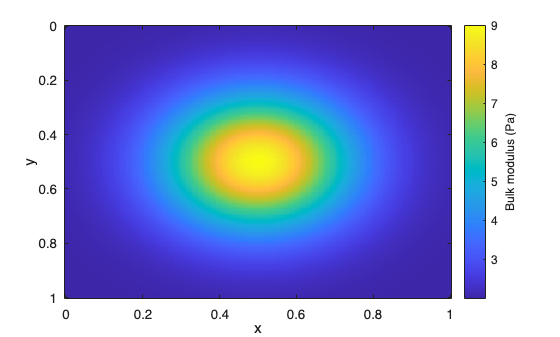

clear

% Computational and output grids
domain = [0,1];
x_cmp = Grid1DUnifPrimal(domain,161);
y_cmp = Grid1DUnifPrimal(domain,161);
grid_cmp = GridSpace2D(x_cmp,y_cmp);

x_out = Grid1DUnifPrimal(domain,81);
y_out = Grid1DUnifPrimal(domain,81);
grid_out = GridSpace2D(x_out,y_out);

% Smooth pressure source centered away from the boundary
xc = 0.25; xw = 0.045;
yc = 0.25; yw = 0.045;
tc = 0.08; tw = 0.018;
source = AcousticSource2D( ...
    @(x,y) exp(-((x-xc)/xw).^2-((y-yc)/yw).^2), ...
    @(t) exp(-((t-tc)/tw).^2));

% Homogeneous acoustic medium
% medium = AcousticMedium2D.constant(KappaValue=1,BetaValue=1);
medium = AcousticMedium2D.gaussianPeak( ...
    BetaRange=[1/2,1], ...
    KappaRange=[2,9], ...
    Center=[0.5,0.5], ...
    Width=0.25);

[kappa_gf,betax_gf,~,c_gf,cMax] = sampleMedium2D(grid_cmp,medium);
kappa_gf.plot;

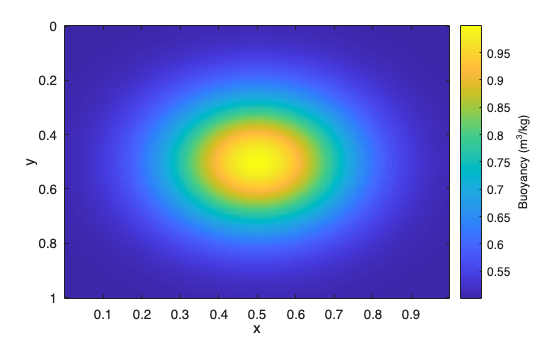

betax_gf.plot;

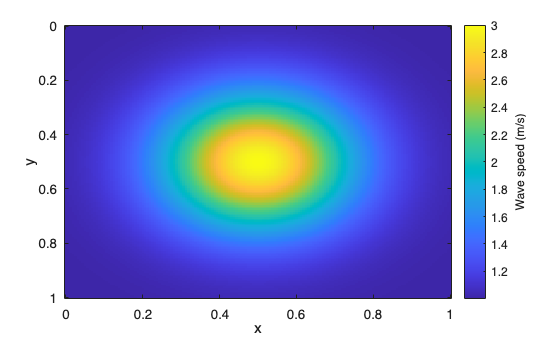

c_gf.plot;


% Select a stable time step for the fourth-order spatial discretization.
spatialOrder = 4;
cflLimit = 6/7;
dt = 0.80*cflLimit/(cMax*sqrt(sum(1./grid_cmp.h.^2)));

finalTime = 0.8;
times_cmp = 0:dt:finalTime;
times_out = linspace(0,times_cmp(end),61);

% Zero initial pressure and velocity
p0 = @(x,y) zeros(size(x));
vx0 = @(x,y) zeros(size(x));
vy0 = @(x,y) zeros(size(x));

solver = AcousticSolver2DStaggered( ...
    grid_cmp,times_cmp,grid_out,times_out,medium, ...
    SpatialOrder=spatialOrder);

% Run the solver
[P,Vx,Vy] = solver.solve(p0,vx0,vy0,Source=source);

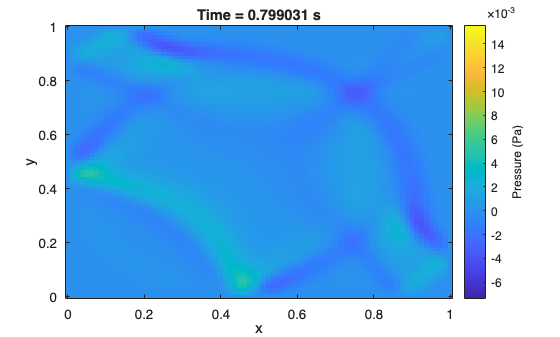

% Animate pressure
ax = axes(figure(Name="Pressure"));
P.animate(FramePause=0.03,Parent=ax);

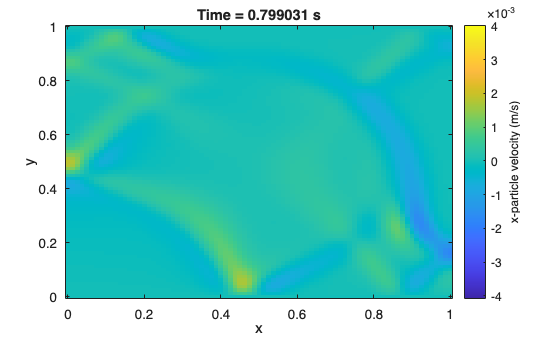

% Animate the x-velocity
ax = axes(figure(Name="x-velocity"));
Vx.animate(FramePause=0.03,Parent=ax);

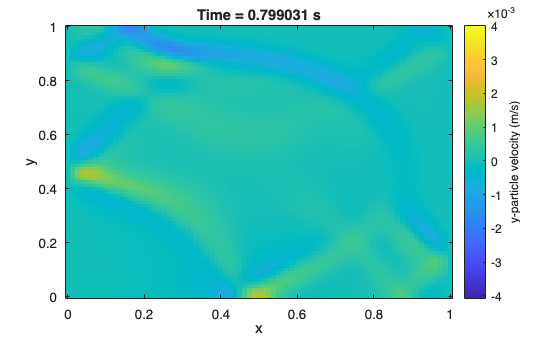

% Animate the y-velocity
ax = axes(figure(Name="y-velocity"));
Vy.animate(FramePause=0.03,Parent=ax);

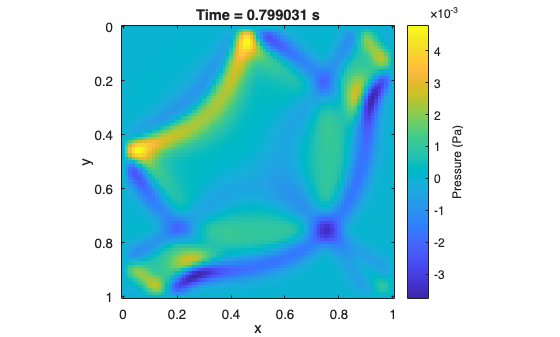

% Plot the final pressure snapshot
ax = axes(figure(Name="Final pressure"));
finalPressure = P.snapshot(P.Nt);
finalPressure.plot(Parent=ax);
axis image
title(P.formattedTime(P.Nt));